a=1;
b=2;
c=2;
p=[a b c];
roots(p)

ans =   -1.0000 + 1.0000i
  -1.0000 - 1.0000i


Comportamento da funçao de transferencia pelo impulso

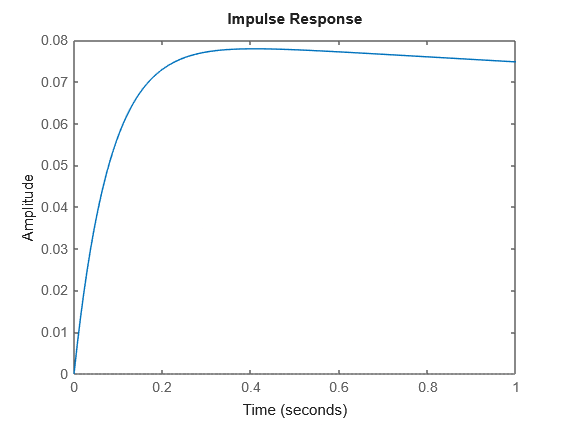

s=tf('s');
H=1/(s^2+12.5*s+1);
impulse(H,1)

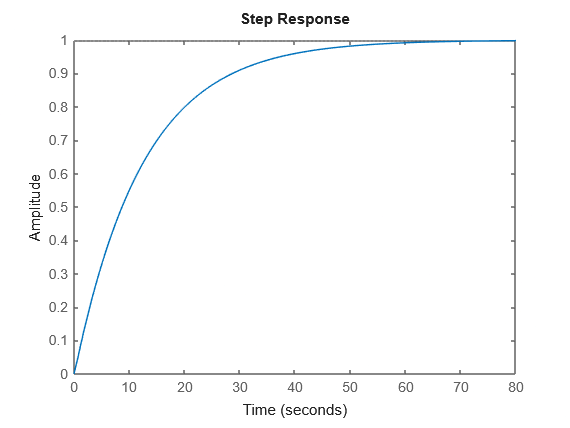

figure
step(H)

Solução dos coeficientes da particular

mat.resp=[0.2;0]; % alterar conforme questao
coef=[-0.05 1.5375;1.5375 0.05]; % alterar conforme questao
resp_p=inv(coef)*mat.resp

resp_p =    -0.0042
    0.1299


Solução dos coeficientes da natural

mat.resp2=[2.5;0];
coef2=[1 1;-161/200 -12419/1000];
resp_n=inv(coef2)*mat.resp2

resp_n =     2.6733
   -0.1733


Y natural

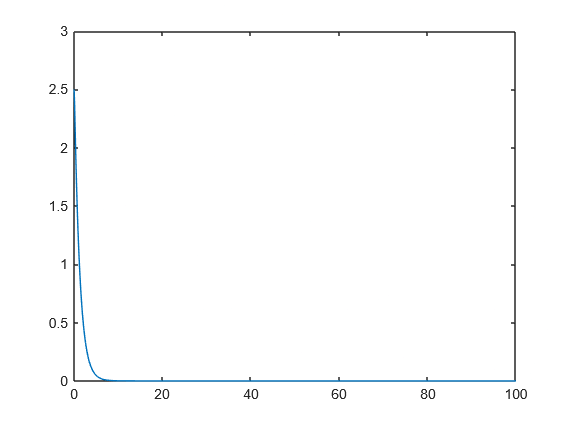

t=0:0.001:100;
C1 = resp_n(1,1);
C2 = resp_n(2,1);
r1 =-161/200;
r2 =-12419/1000;
Yn=C1*exp(r1*t)+C2*exp(r2*t); % alterar conforme questao
plot(t,Yn)

Y forçado

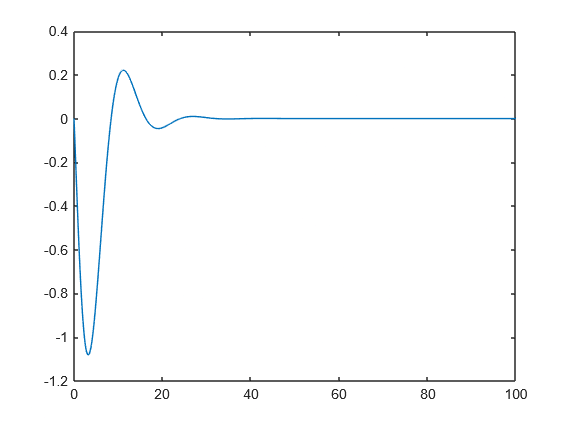

t=0:0.001:100;
Yf=exp(-1/5*t).*((1/2)*cos(2/5*t)-(9/4)*sin(2/5*t))-(1/2)*exp(-t); % alterar conforme questao
plot(t,Yf)

Frequencia natural

Wn=(c/a)^(1/2)

Wn = 1.4142

Atenuação

sigma=-b/(2*a)

sigma = -1

Frequencia nat. amortecida

Wd=(Wn^2-sigma^2)^(1/2)

Wd = 1.0000

GABARITO

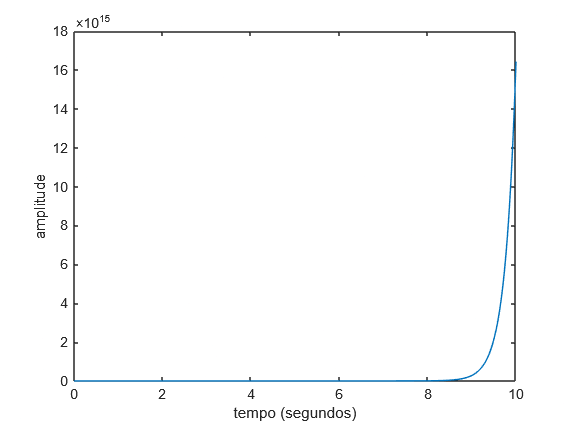

close all
tspan = 0:1/100:10;
y0=[0 0];
[t,y] = ode45(@eq_dif, tspan,y0);
plot(t,y(:,1));
xlabel('tempo (segundos)')
ylabel('amplitude')


function dydt = eq_dif(~,y)
    u=1;
    dydt = [y(2);1*y(2)+12.5*y(1)+u];
end